% Transfer learning GoogLeNet

clear
imds = imageDatastore("MerchData", ...
                        "IncludeSubfolders",true, "LabelSource","foldernames");


numClasses = 5;

net = googlenet;

inputSize = net.Layers(1);
outSize = net.Layers(end);

[train, valid] = splitEachLabel(imds, 0.70, "randomize");

audsTrain = augmentedImageDatastore(inputSize.InputSize, train);
audsValid = augmentedImageDatastore(inputSize.InputSize, valid);


layersTransfer = layerGraph(net);

layer = fullyConnectedLayer(5,'Name',"fc");
layersTransfer = replaceLayer(layersTransfer, "loss3-classifier", layer);

layer = classificationLayer("Name", 'output');
layersTransfer = replaceLayer(layersTransfer, 'output', layer);



opts = trainingOptions("sgdm", "InitialLearnRate",0.0001, "MaxEpochs",6 ...
                        ,"MiniBatchSize",10, "ValidationData",audsValid ...
                        , "ValidationFrequency",3, "Plots","training-progress" ...
                        ,"Verbose",false)

opts =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-04
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 6
               MiniBatchSize: 10
                     Verbose: 0
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 3
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddin


[MerchNet, info] = trainNetwork(audsTrain, layersTransfer, opts)

MerchNet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


info = struct with fields:
               TrainingLoss: [3.4596 3.2729 3.7010 2.5185 3.2656 2.7498 2.3064 2.6513 1.7572 1.2592 1.1414 1.2112 1.4814 1.0926 0.5091 0.7713 0.6890 0.2939 0.9177 0.5107 0.4997 0.3281 0.2321 0.3610 0.3284 0.2158 0.1719 0.0775 0.2685 0.4589]
           TrainingAccuracy: [20 10 20 20 20 10 30 10 40 40 50 60 30 60 80 50 80 100 60 70 80 80 100 90 90 90 100 100 90 90]
             ValidationLoss: [2.6806 NaN 2.4608 NaN NaN 1.9786 NaN NaN 1.4681 NaN NaN 1.0396 NaN NaN 0.7027 NaN NaN 0.4798 NaN NaN 0.3322 NaN NaN 0.2419 NaN NaN 0.1846 NaN NaN 0.1491]
         ValidationAccuracy: [15 NaN 25 NaN NaN 35 NaN NaN 55.0000 NaN NaN 55.0000 NaN NaN 60 NaN NaN 75 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95]
              BaseLearnRate: [1×30 double]
        FinalValidationLoss: 0.1491
    FinalValidationAccuracy: 95




testpreds = classify(MerchNet, audsValid)

testpreds = 20×1 categorical array
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Torch 
     MathWorks Torch 
     MathWorks Torch 
     MathWorks Cap 


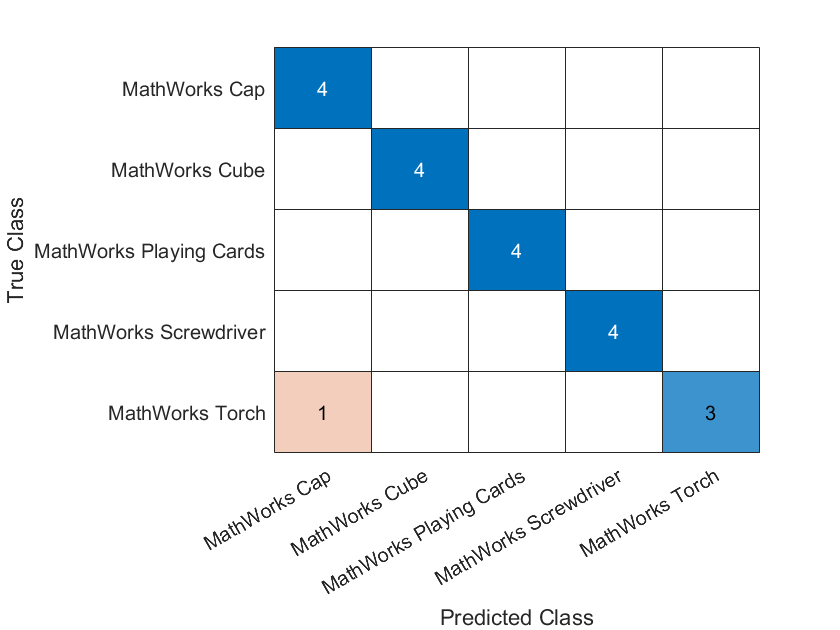


MerchActual = valid.Labels;
confusionchart(MerchActual, testpreds)

numCorrect = nnz(testpreds == MerchActual);
fracCorrect = numCorrect/20

fracCorrect = 0.9500

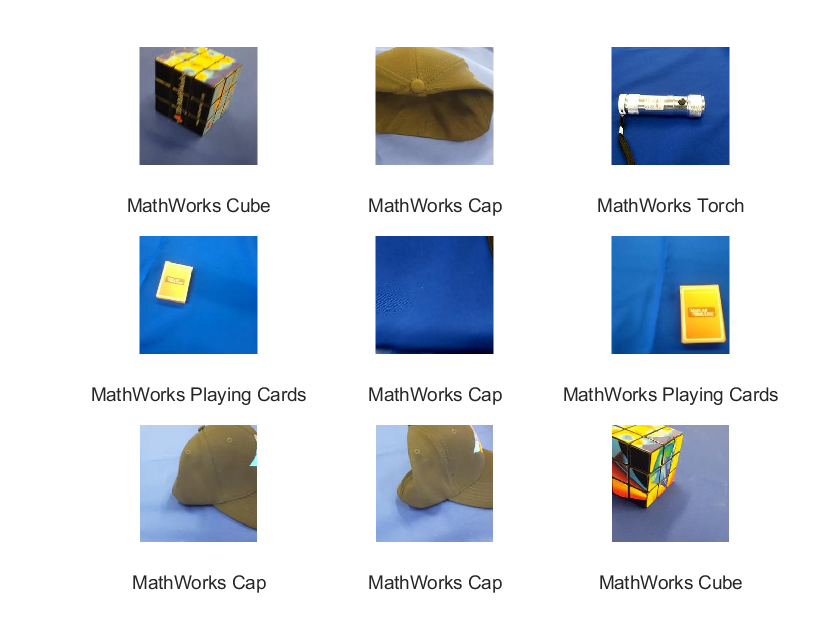



figure;
perm = randperm(20,9);
for k = 1:9
 subplot(3,3,k);
 imshow( valid.Files{ perm(k) } )
 xlabel(testpreds(perm(k)))
end